# Dynamic Model of Two Wheel Self Balancing Robot

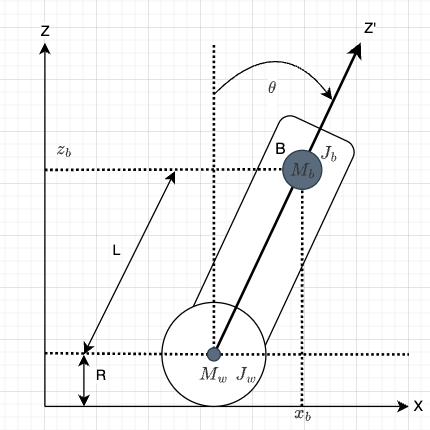

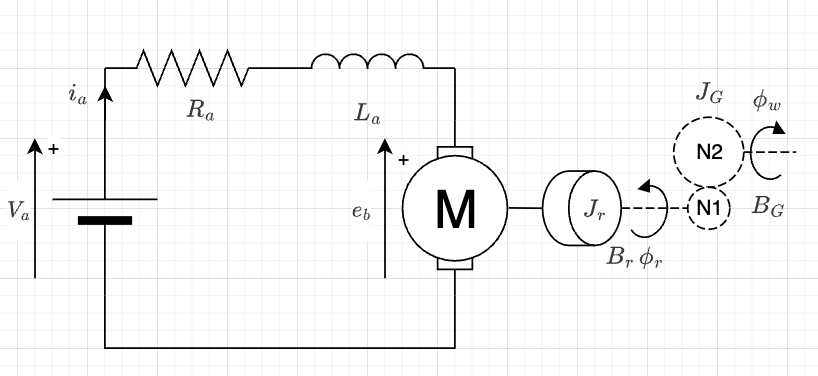

Steady State

$T_m \left(t\right)=K_t \cdot i_a \left(t\right)\;$ torque generate by motor rotor

$J_r \cdot {\ddot{\phi} }_r +B_r \cdot {\dot{\phi} }_r =K_t \cdot i_a \left(t\right)\;$ mechancial torque balance equation

$V_a \left(t\right)=i_a \left(t\right)\cdot R_a +e_b \left(t\right)$ kcl 


$$e_b \left(t\right)=K_e \cdot {\dot{\phi} }_r \;$$
 

$\Omega_w \left(s\right)=\frac{N_2 }{N_1 }\cdot {s\phi }_r$ output shaft speed


$$T_w \left(s\right)=\frac{N_2 }{N_1 }\cdot T_m \left(s\right)-s\cdot B_G$$
 


$$J_{\textrm{eq}} =J_G +{\left(\frac{\textrm{N1}}{\textrm{N2}}\right)}^2 \cdot J_r$$


Transfer Function DC Motor


$$\frac{\Omega_w \left(s\right)}{V_a \left(s\right)}=\frac{K_t }{s^2 \cdot L_a R_a +\;s\left(R_a \cdot J_{\mathrm{eq}} +B_{\mathrm{eq}} \cdot L_a \right)+K_t {\cdot K}_e +R_a \cdot B_q }\cdot n$$
 

clear
Jr = 3.2284E-5;   % rotational inertia        [Nms^2/rad]
Jg = 3.22E-5;
Bg = 0;           % vicous friction           [Nms/rad]
Kt = 0.9;      % Motor Torque constant        []
Ke = 0.1;      % Motor Back EMF constant      []
Ra = 1.2;         % armature resistance       [Ω]
La = 0;           % armature inductance          [H]
N1=1;
N2 = 20;
n = N1/N2;
s = tf("s"); 
motor_simp_tf = Kt*n / (s*(Ra*Jg + Jr*(n)^2) + Kt*Ke)


motor_simp_tf =
 
        0.045
  ------------------
  3.872e-05 s + 0.09
 
Continuous-time transfer function.
Model Properties



step(motor_tf); hold on; step(tf1ct); grid on; grid minor; hold off; legend("Cannonical","Identified");

Unrecognized function or variable 'motor_tf'.

clear
s = tf("s"); 
Ra = 1.4;
n = 20;
Kt = ureal('Kt', 0.08, 'Percentage', 10);   % ±10% uncertainty in K
Ke = ureal('Ke', 0.08, 'Percentage', 10);   % ±10% uncertainty in K
Jr = ureal('Jr', 0.01, 'Percentage', 10); % ±10% uncertainty in J
Jg = ureal('Jg', 0.01, 'Percentage', 10); % ±10% uncertainty in J


motor_simp_tf = Kt / (s*(Ra*Jg + Jr*(n)^2) + Kt*Ke) * n

Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 3 states.
The model uncertainty consists of the following blocks:
  Jg: Uncertain real, nominal = 0.01, variability = [-10,10]%, 1 occurrences
  Jr: Uncertain real, nominal = 0.01, variability = [-10,10]%, 1 occurrences
  Ke: Uncertain real, nominal = 0.08, variability = [-10,10]%, 1 occurrences
  Kt: Uncertain real, nominal = 0.08, variability = [-10,10]%, 2 occurrences


[~, cl_chirp_rpm, cl_chirp_ref, cl_chirp_u] = extractMotorData("DataSets/cl_zn_chrip8_1.csv");

num_samples = 1000; % Number of Monte Carlo samples
y = simsd(motor_simp_tf, cl_chirp_ref') 

Incorrect number or types of inputs or outputs for function simsd.